% 16-714 Advanced Control for Robotics
% extra credit
% Yutong Huang
clc;clear;
close all;


## Initialization

global robot;
robot = loadrobot('kinovaGen3','DataFormat','row','Gravity',[0 0 -9.81]);

goal = [0.4,0,0.6];
x0 = homeConfiguration(robot);
x0 = [x0;zeros(1,7)];
endEffector = "EndEffector_Link";
taskInit = getTransform(robot,x0(1,:),endEffector);
taskFinal = trvec2tform(goal)*axang2tform([0 1 0 pi]);
ik = inverseKinematics("RigidBodyTree",robot);
xT = ik(endEffector,taskFinal,[1 1 1 1 1 1],x0(1,:));
xT = mod(xT,2*pi);
xT = [xT;zeros(1,7)];

% Time parameters
Tmax = 5;
dt = 0.05;
tlist = 0:dt:Tmax;
Nsteps = length(tlist);

% MPC horizon
N_horizon = 15;

## Extend System Matrices for all 7 joints together

nx = 14; % 7 pos + 7 vel
nu = 7;
A = [eye(7), dt*eye(7); zeros(7), eye(7)];
B = [zeros(7); dt*eye(7)];

% Cost weights
Q = blkdiag(5*eye(7), 1*eye(7)); % State cost weights
R = 0.1*eye(7);                  % Input cost weights

## Load reference trajectory

load_from_lqr = 1;
if load_from_lqr
    load('ref_traj.mat', 'xlist');
    ref_traj = xlist;
else
    ref_traj = zeros(2,7,Nsteps);
    ref_traj(:,:,1) = x0;
    ref_traj(:,:,end) = xT;
    % linear interpolation the reference trajectory
    for i = 2:Nsteps-1
        ref_traj(:,:,i) = ref_traj(:,:,1) + (ref_traj(:,:,end) - ref_traj(:,:,1)) * (i-1)/(Nsteps-1);
    end
    % find the velocity besed on the reference trajectory
    for i = 1:Nsteps-1
        ref_traj(2,:,i) = (ref_traj(1,:,i+1) - ref_traj(1,:,i))/dt;
    end
end

## Extended dynamics

bar_B = zeros((N_horizon+1)*nx, N_horizon*nu);
for i = 0:N_horizon-1
    for j = 0:i
        bar_B((i+1)*nx+1:(i+2)*nx, j*nu+1:(j+1)*nu) = A^(i-j)*B;
    end
end
bar_A = eye(14);
for i=0:N_horizon-1
    bar_A = [eye(14); bar_A * A];
end

## Extended costs

bar_Q = kron(eye(N_horizon+1), Q);
bar_R = kron(eye(N_horizon), R);
QQ = bar_B'*bar_Q*bar_B + bar_R;

## constraints

u_max = 25;
v_max = 20; 

% Accelration constraint
u_max = u_max*ones(nu,1);
u_min = -u_max;
lb = repmat(u_min, N_horizon, 1);
ub = repmat(u_max, N_horizon, 1);

% Velocity constraint
v_max = v_max * ones(7*(N_horizon+1),1); 
C_vel = zeros((N_horizon+1)*7, (N_horizon+1)*nx);
for i = 0:N_horizon
    C_vel(i*7+1:(i+1)*7, i*nx+8:i*nx+14) = eye(7);
end

## MPC Loop

% Store simulation data
xlist = zeros(nx,Nsteps);
xlist(:,1) = x0(:);
ulist = zeros(nu,Nsteps-1);
u_perd_list = zeros(7*N_horizon,Nsteps-1);
for k = 1:Nsteps-1
    x_curr = xlist(:,k);

    % Extract the reference for the horizon
    if k+N_horizon <= Nsteps
        ref_hor = ref_traj(:,:,k:k+N_horizon);
    else
        ref_hor = ref_traj(:,:,k:end);
        last_ref = ref_traj(:,:,end);
        while size(ref_hor,3) < N_horizon+1
            ref_hor = cat(3, ref_hor, last_ref);
        end
    end
    % Reshape reference into a single vector
    ref_vec = [];
    for i=1:N_horizon+1
        x_ref_i = [ref_hor(1,:,i), ref_hor(2,:,i)]'; % pos, vel
        ref_vec = [ref_vec; x_ref_i];
    end

    CC = (bar_A*x_curr - ref_vec)'*bar_Q*bar_B; 
    CC = CC';

    A_vel = [ C_vel*bar_B; -C_vel*bar_B];
    b_vel = [ v_max - C_vel*bar_A*x_curr;
              v_max + C_vel*bar_A*x_curr];

    % Solve QP
    options = optimoptions('quadprog','Display','off');
    U = quadprog(QQ, CC, A_vel, b_vel, [], [], lb, ub, [], options);

    % Apply the first control input
    u_applied = U(1:nu);
    ulist(:,k) = u_applied;

    %save perdicted U
    u_perd_list(:,k) = U;

    % Simulate forward one step
    x_next = A*x_curr + B*u_applied;
    xlist(:,k+1) = x_next;
end

## visualize

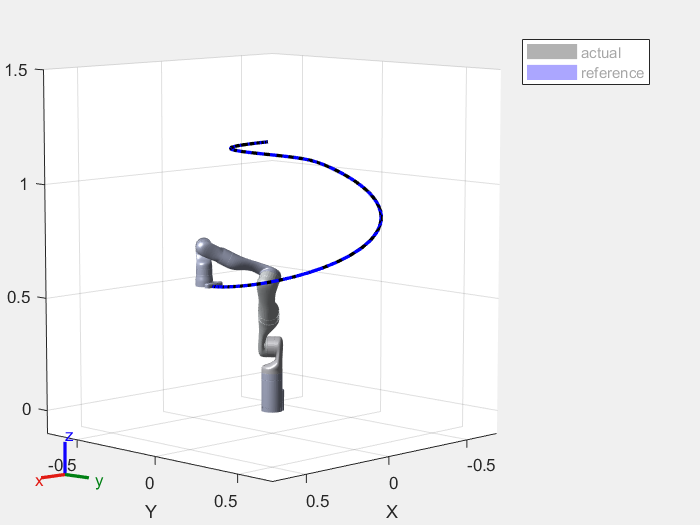

visualize_arm = 0;
% Visualization setup
figure(1); clf;
clist = zeros(length(tform2trvec(taskInit)),length(tlist)); 
clist(:,1) = tform2trvec(taskInit)';
c_ref_list = zeros(length(tform2trvec(taskInit)),length(tlist)); 
c_ref_list(:,1) = tform2trvec(taskInit)';
for k = 2:length(tlist)
    x = ref_traj(1,:,k);
    c_ref_list(:,k) = tform2trvec(getTransform(robot,x,endEffector))';
end
for k = 2:length(tlist)
    x = xlist(1:7,k)';
    if visualize_arm
        pause(dt/10);
        show(robot,x,'PreservePlot',true,'Frames','off');
    end
    axis([-0.7 0.7 -0.7 0.7 -0.1 1.5]);
    clist(:,k) = tform2trvec(getTransform(robot,x,endEffector))';
end
pause(dt);
show(robot,x,'PreservePlot',true,'Frames','off');
hold on;
plot3(clist(1,:),clist(2,:),clist(3,:),'k','LineWidth',2);
hold on;
plot3(c_ref_list(1,:),c_ref_list(2,:),c_ref_list(3,:),'b','LineWidth',2);
legend(["actual", "reference"]);
axis([-0.7 0.7 -0.7 0.7 -0.1 1.5]);

## plot control tarj

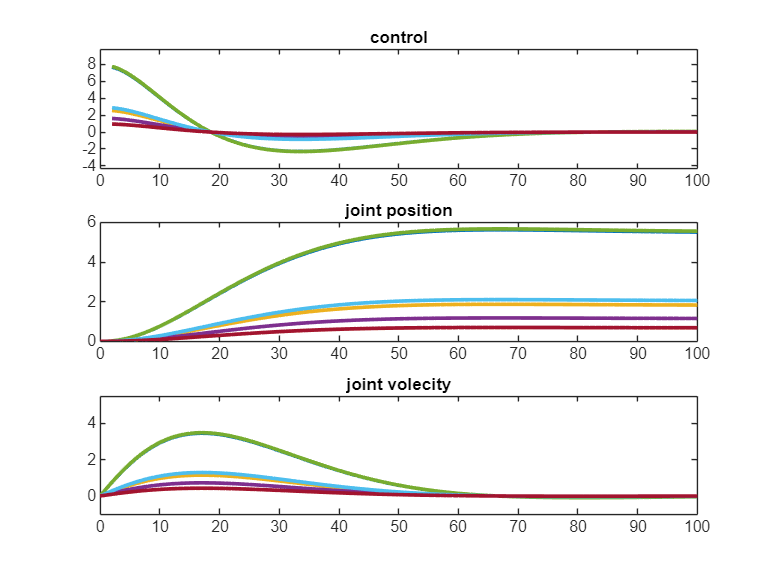

figure(2);
subplot(3,1,1)
plot(2:length(tlist), ulist,'LineWidth',2);
title("control")
xlim([0 100])
ylim([min(min(ulist))-2 max(max(ulist))+2])
yline(u_max, 'r--', 'u_{max}','LineWidth',2);
yline(u_min, 'r--', 'u_{min}','LineWidth',2);
subplot(3,1,2)
plot(0:Nsteps-1, xlist(1:7,:)','LineWidth',2);
title("joint position")
xlim([0 100])
subplot(3,1,3)
plot(0:Nsteps-1, xlist(8:14,:)','LineWidth',2);
title("joint volecity")
xlim([0 100])
ylim([-1 max(max(xlist(8:14,:)))+2])
yline(v_max, 'r--', 'v_{max}','LineWidth',2);
yline(-v_max, 'r--', 'v_{min}','LineWidth',2);

## MPC perdiction plot

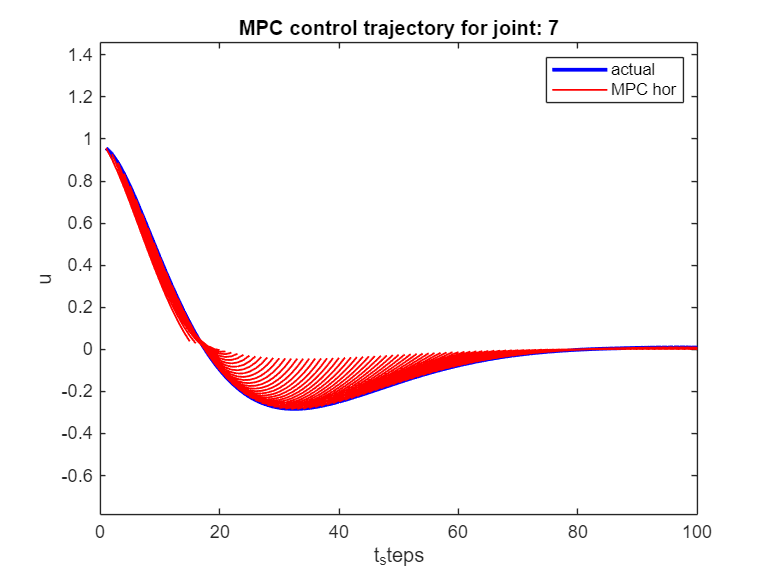

joint = 7; % 1-7 joint

figHandle = findobj('Type', 'figure', 'Number', 3);
if ~isempty(figHandle)
    close(3);
end
figure(3)
p1 = plot(1:Nsteps-1, ulist(joint,:),'b','LineWidth',2); hold on;
u_joint_mpc_hor = zeros(1,N_horizon);
for i = 1:Nsteps-1
    for j = 1:N_horizon
        u_idx = (j-1)*7+joint;
        u_joint_mpc_hor(j) = u_perd_list(u_idx,i);
    end
    p2 = plot(i:i+N_horizon-1, u_joint_mpc_hor,'r','LineWidth',1); hold on;
end
xlim([0 100])
ylim([min(ulist(joint,:))-0.5 max(ulist(joint,:))+0.5])
xlabel("t_steps")
ylabel("u")
title("MPC control trajectory for joint: " + num2str(joint))
legend([p1, p2], {'actual', 'MPC hor'});